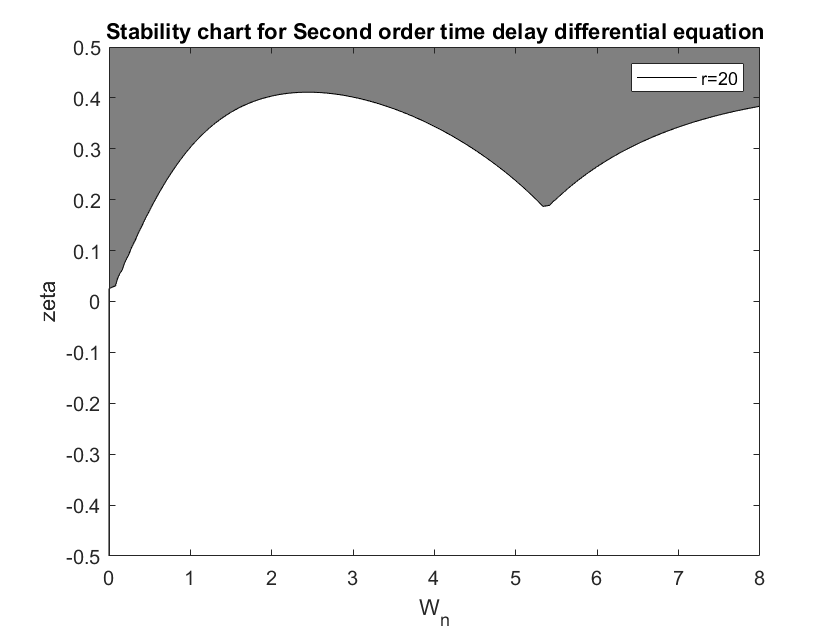

%Semidistritization of a second order differential equation. HW3 Ques2;
% x''(t) + 2*z*w_n*x'(t) + w_n^2*(x(t) + (3/4)*x(t-tau)) = 0
% P = exp(A*deltat) ; R = inv(A)*(P-I)*B : P and R will always have this
% formula. Just the dimension of A and B will change depending on the order
% of the differential equation.

%Convert second order differential equatoin into two first order and then
%calculate A and B.

%Convsrting above second Order  Differential Equation into two songle order
%equations. Let x'(t) = z(t).
%Thus,  x'(t) = z(t)
%       z'(t) = -2*z*w_n*z(t) - w_n^2*(x(t)+(3/4)*x(t-tau))
%    [x'(t) ; z'(t)] = [0 1; -w_n^2  -2*z*w_n]*[x(t) ; z(t)] + [0 0 ; -(3/4)*w_n^2
%    0]*[x(t-tau) ; x'(t-tau)]

%Reference HW3_Q2 Connected Vehicles

tau = 1;
r = 20;
step = 100;
order = 2;
syms t;

omega_n_v = linspace(0,8,step);
zeta_v = linspace(-0.5,0.5,step);
deltat = tau/r;

[omega_n,zeta] = meshgrid(omega_n_v,zeta_v);
eigcr = zeros(length(omega_n),length(zeta_v));

G = zeros(order*(r+1));
G(1+order:end,1:end-order) = eye(order*r);

for ka=1:length(omega_n_v)
    for kb = 1:length(zeta_v)
        A = [0 1; -omega_n_v(ka)^2  -2*zeta_v(kb)*omega_n_v(ka)];
        B = [0 0 ; -(3/4)*omega_n_v(ka)^2 0];
        P = expm(A*deltat);
        if det(A) == 0
          R = eval(int(expm(A*(deltat-t)),t,0,deltat)*B);
        else
          R = inv(A)*(P-eye(2))*B;  
        end  
        G(1:2,1:2) = P;
        G(1:2,end-1:end) = R;
        eigcr(kb,ka) = max(abs(eig(G)));
    end
end

contourf(omega_n,zeta,-eigcr,[-1 -1],'k');
colormap gray
xlabel('W_n');
ylabel('zeta');
title('Stability chart for Second order time delay differential equation');
legend(['r=',num2str(r)]);